**1)**


format long  e
A=pd(5);
G=(mychol(A))'

G =      1.628114501765485e+00     2.773772250683555e-03     1.490790710268316e-02     5.961691798686955e-02     4.013140322868558e-02
                         0     1.643082583938136e+00    -1.015783571189407e-01    -4.894179374517545e-02     2.354210672842965e-02
                         0                         0     1.574002229508007e+00    -6.039894143678427e-02     2.055357606143739e-03
                         0                         0                         0     1.625953055224087e+00    -4.767078336969791e-02
                         0                         0                         0                         0     1.647281811598364e+00






G_hat=chol(A)

G_hat =      1.628114501765485e+00     2.773772250683538e-03     1.490790710268316e-02     5.961691798686955e-02     4.013140322868558e-02
                         0     1.643082583938136e+00    -1.015783571189408e-01    -4.894179374517545e-02     2.354210672842952e-02
                         0                         0     1.574002229508007e+00    -6.039894143678427e-02     2.055357606143732e-03
                         0                         0                         0     1.625953055224087e+00    -4.767078336969784e-02
                         0                         0                         0                         0     1.647281811598364e+00


norm(G-G_hat)

ans =      1.764715330268963e-16


**2)**

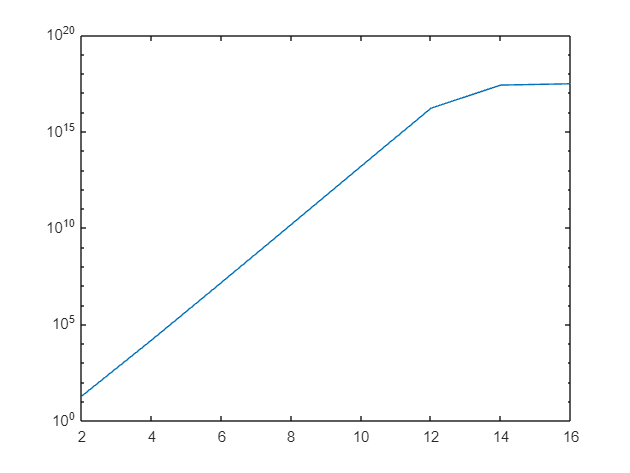

C=[];
N= 2:2:16;
for n=N
H=hilb(n);
C=[C; cond(H)];
end
semilogy(N,C)

**1-norm**

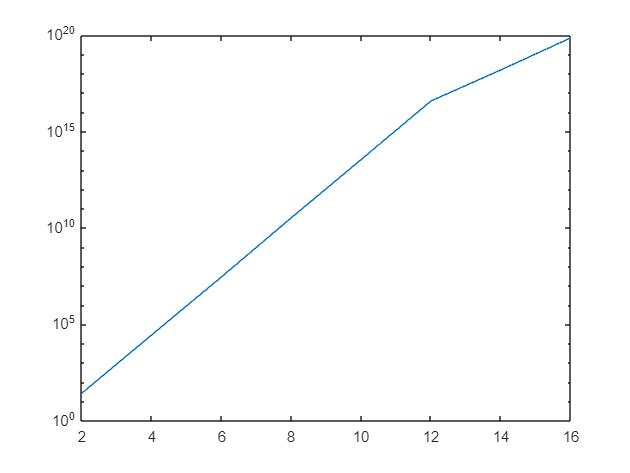

C=[];
N= 2:2:16;
for n=N
H=hilb(n);
C=[C; cond(H,1)];
end
semilogy(N,C)

**inf-norm**

C=[];
N= 2:2:16;
for n=N
H=hilb(n);
C=[C; cond(H,inf)];
end
semilogy(N,C)

**3)**

x= randn(5,1)

x =      2.359638835780386e-01
    -7.784213500002719e-01
     1.099561945395381e+00
    -8.555642956360415e-01
     7.557623563150090e-03


H=hilb(5);
b=H*x;
x1=H\b

x1 =      2.359638835780331e-01
    -7.784213500001678e-01
     1.099561945394937e+00
    -8.555642956353799e-01
     7.557623562829688e-03




 n=8;
 H=hilb(n); HI = invhilb(n);
 x= rand(n,1);
 b =H*x;
 x1 = H\ b; x2 = HI*b;
 [P,L,U]=gepp(H);
 c=P*b;
 y=rowforward(L,c);
 x3=colbackward(U,y);
 [x x1 x2 x3]

ans =      9.993294790257193e-01     9.993294790316716e-01     9.993294790365326e-01     9.993294790380015e-01
     3.554071512678812e-01     3.554071510328219e-01     3.554071511607617e-01     3.554071507118724e-01
     4.707770954883395e-02     4.707771184391940e-02     4.707772098481655e-02     4.707771586638816e-02
     2.136605851207991e-01     2.136605758331250e-01     2.136606276035309e-01     2.136605547421586e-01
     3.978391241027053e-01     3.978391425456013e-01     3.978390395641327e-01     3.978391979169813e-01
     3.336681803802948e-01     3.336681617256377e-01     3.336681723594666e-01     3.336680849683594e-01
     2.296025319681976e-01     2.296025409003485e-01     2.296026349067688e-01     2.296025946004210e-01
     9.361201775020683e-01     9.361201760058775e-01     9.361201971769333e-01     9.361201610717044e-01


 [cond(H) norm(x-x1)/norm(x) norm(x-x2)/norm(x) norm(x-x3)/norm(x)]

ans =      1.525757553064797e+10     1.906242115375734e-08     9.213246217445172e-08     9.116091647075323e-08


 n=10;
 H=hilb(n); HI = invhilb(n);
 x= rand(n,1);
 b =H*x;
 x1 = H\ b; x2 = HI*b;
 [P,L,U]=gepp(H);
 c=P*b;
 y=rowforward(L,c);
 x3=colbackward(U,y);
 [x x1 x2 x3]

ans =      6.831887846999827e-01     6.831887848852649e-01     6.831887848093174e-01     6.831887860849424e-01
     9.621137957228634e-01     9.621137776519784e-01     9.621137380599976e-01     9.621136736259667e-01
     4.379731776327981e-01     4.379735964402608e-01     4.379737377166748e-01     4.379758183428639e-01
     9.403366544209071e-01     9.403326013864267e-01     9.403238296508789e-01     9.403123574483011e-01
     5.834324572370875e-03     5.854613384569257e-03     5.920410156250000e-03     5.951343898316616e-03
     6.103070300698753e-01     6.102490678049440e-01     6.100769042968750e-01     6.099827738826100e-01
     8.010757569661195e-01     8.011738905282645e-01     8.011779785156250e-01     8.016113150971456e-01
     2.329815334136481e-01     2.328841864550922e-01     2.326965332031250e-01     2.324610481925482e-01
     9.324686759209786e-01     9.325209245938021e-01     9.326782226562500e-01     9.327432542587722e-01
     7.632627753337419e-01     7.632510653613737e

 [cond(H) norm(x-x1)/norm(x) norm(x-x2)/norm(x) norm(x-x3)/norm(x)]

ans =      1.602491707013505e+13     7.185835443039180e-05     1.986021991754000e-04     3.893305740931084e-04


  n=11;
 H=hilb(n); HI = invhilb(n);
 x= rand(n,1);
 b =H*x;
 x1 = H\ b; x2 = HI*b;
 [P,L,U]=gepp(H);
 c=P*b;
 y=rowforward(L,c);
 x3=colbackward(U,y);
 [x x1 x2 x3]

ans =      8.264495397026816e-01     8.264495361569208e-01     8.264495334587991e-01     8.264495406416412e-01
     5.734635886048661e-01     5.734639599960398e-01     5.734639465808868e-01     5.734634909062984e-01
     7.925816641202259e-01     7.925720309180654e-01     7.925662994384766e-01     7.925842002415460e-01
     3.290411958392475e-01     3.291488548105851e-01     3.291702270507812e-01     3.290127359283130e-01
     2.234619761258525e-01     2.228209284058825e-01     2.238159179687500e-01     2.236323837424814e-01
     3.123863420192535e-01     3.146389724752954e-01     3.137207031250000e-01     3.117838649476008e-01
     5.845234785285556e-01     5.796213692276830e-01     5.776367187500000e-01     5.858427159048774e-01
     8.299141410215228e-01     8.365936416138731e-01     8.364257812500000e-01     8.281056769681479e-01
     2.904624915472681e-01     2.849169294881288e-01     2.797851562500000e-01     2.919726567967663e-01
     4.025543920631225e-01     4.051189585233886e

 [cond(H) norm(x-x1)/norm(x) norm(x-x2)/norm(x) norm(x-x3)/norm(x)]

ans =      5.226577898439322e+14     5.341614215409833e-03     8.054121253473273e-03     1.446812306224037e-03


 n=12;
 H=hilb(n); HI = invhilb(n);
 x= rand(n,1);
 b =H*x;
 x1 = H\ b; x2 = HI*b;

 [P,L,U]=gepp(H);
 c=P*b;
 y=rowforward(L,c);
 x3=colbackward(U,y);
 [x x1 x2 x3]

ans =      6.147395502163996e-01     6.147395298260547e-01     6.147394962608814e-01     6.147395207110335e-01
     9.911877883297928e-01     9.911903748151184e-01     9.911907911300659e-01     9.911914829297109e-01
     2.036988751856221e-01     2.036175366877160e-01     2.035789489746094e-01     2.035838383153117e-01
     8.272090849466549e-01     8.283166814751520e-01     8.273315429687500e-01     8.287632829460829e-01
     6.758616189527743e-01     6.677491955982594e-01     6.665039062500000e-01     6.645504624069445e-01
     2.489494700398081e-01     2.845556931621243e-01     2.500000000000000e-01     2.983344876220080e-01
     4.757856265695326e-01     3.766924009228316e-01     2.109375000000000e-01     3.389518904721028e-01
     3.990752267267919e-01     5.782316030682213e-01     7.265625000000000e-01     6.455358281952082e-01
     5.994382490914121e-01     3.896536460453951e-01     2.968750000000000e-01     3.117765329697703e-01
     8.005227658038510e-01     9.539813569627623e

 [cond(H) norm(x-x1)/norm(x) norm(x-x2)/norm(x) norm(x-x3)/norm(x)]

ans =      1.622382674081028e+16     1.568177297720560e-01     2.723381709889028e-01     2.152207298421855e-01


**GEPP and  HI*b do not give accurate results**

**4)**

 n=10;
H=hilb(n); x = randn(n,1);
b = H*x;
x1= H \ b;
r = H*x1-b;
disp( [norm(r)/norm(b) norm(x-x1)/norm(x)])

     9.653864971391168e-17     1.131982228870812e-04



**small ||r||/||b|| does not imply ||x − xˆ||/||x|| .**

**5)**

% n = 32
n = 32;
W = wilkinson(n);
x = randn(n,1);
b = W*x;

% --- GEPP ---
[P,L,U] = gepp(W);
c = P*b;
y = rowforward(L,c);
x_hat = colbackward(U,y);
fe1 = norm(x-x_hat,inf)/norm(x,inf);   % forward error
c1  = cond(W,inf);                     % condition number
r1  = W*x_hat - b;
e1  = norm(r1,inf)/norm(b,inf);        % relative residual

% --- QR ---
[Q,R] = qr(W);
y = Q'*b;
x_qr = colbackward(R,y);
fe1_qr = norm(x-x_qr,inf)/norm(x,inf);
r1_qr  = W*x_qr - b;
e1_qr  = norm(r1_qr,inf)/norm(b,inf);

% for n=64
n = 64;
W = wilkinson(n);
x = randn(n,1);
b = W*x;

% GEPP
[P,L,U] = gepp(W);
c = P*b;
y = rowforward(L,c);
x_hat = colbackward(U,y);
fe2 = norm(x-x_hat,inf)/norm(x,inf);
c2  = cond(W,inf);
r2  = W*x_hat - b;
e2  = norm(r2,inf)/norm(b,inf);

% QR
[Q,R] = qr(W);
y = Q'*b;
x_qr = colbackward(R,y);
fe2_qr = norm(x-x_qr,inf)/norm(x,inf);
r2_qr  = W*x_qr - b;
e2_qr  = norm(r2_qr,inf)/norm(b,inf);

Results = table(...
    ["GEPP";"QR";"GEPP";"QR"], ...     
    [32;32;64;64], ...                
    [fe1; fe1_qr; fe2; fe2_qr], ...   
    [c1; c1; c2; c2], ...                
    [e1; e1_qr; e2; e2_qr], ...        
    'VariableNames', {'Method','n','ForwardError','CondInf','RelativeResidual'})

Results = 4×5 table
    Method             n                  ForwardError              CondInf             RelativeResidual  
    ______    ____________________    ____________________    ____________________    ____________________

    "GEPP"    3.20000000000000e+01    1.58082078304248e-16    1.00578296116360e+02    1.26167659720772e-16
    "QR"      3.20000000000000e+01    6.12568053428961e-16    1.00578296116360e+02    2.52335319441544e-16
    "GEPP"    6.40000000000000e+01    1.80143457213199e-16    1.98108765077681e+02    1.36885640481594e-16
    "QR"      6.40000000000000e+01    1.91402423289024e-15    1.98108765077681e+02    4.10656921444782e-16


**GEPP** gave a lower forward error in both tests.

**Neither**. The rule of thumb provided a loose upper bound that significantly overestimated the actual error for both methods.

**GEPP** produced a slightly lower relative residual in both experiments.

**Both methods are backward stable**, as shown by their very small relative residuals, which were on the order of machine precision.

# FUNCTIONS

function A = pd(n)
    a = 2; 
    b = 3;
    r = a + (b - a) .* rand(n, 1);
    D = diag(r);
    B = randn(n);
    [Q, ~] = qr(B);
    A = Q' * D * Q;
end

function W = wilkinson(n)
    
    m = (n-1)/2;
    D = diag(abs(-m:m)); 
    E = diag(ones(n-1,1), 1); 
    W = D + E + E';
end

function G = mychol(A)


    [n, m] = size(A);
    if n ~= m
        error('Input matrix must be square.');
    end
    if n == 1
        if A(1,1) > 0
            G = sqrt(A(1,1));
        else
            error('Matrix (or a subproblem) is not positive definite.');
        end
        return;
    end
    a11 = A(1,1);     
    b = A(2:n, 1);    
    A_hat = A(2:n, 2:n);

    if a11 <= 0
        error('Matrix is not positive definite.');
    end

    g11 = sqrt(a11);
    g = b / g11;
    A_hat_updated = A_hat - g * g';
    G_hat = mychol(A_hat_updated);
    G = zeros(n, n);
    G(1,1) = g11;
    G(2:n, 1) = g;
    G(2:n, 2:n) = G_hat;

end



function [x] = colbackward(U,b)
    n = size(U,1);
    x = zeros(n,1);
    for i = n:-1:1
        if U(i,i) == 0
            error('Zero pivot on diagonal of U.');
        end
        s = 0;
        for j = i+1:n
            s = s + U(i,j)*x(j);
        end
        x(i) = (b(i) - s)/U(i,i);
    end
end

 function [x] = rowforward(L,b)

    n = length(b);
    x = zeros(n,1);
    for k = 1:n
        if L(k,k) == 0
            error('Zero pivot on diagonal of L.');
        end
        s = 0;
        for j = 1:k-1
            s = s + L(k,j) * x(j);
        end
        x(k) = (b(k) - s) / L(k,k);
    end
 end


function [P,L,U] =gepp(A)
    n = size(A, 1);
       P = eye(n);
    for k =1:n-1
       [~, rowi] = max(abs(A(k:n, k)));
         rowi = rowi + k - 1;
       A([k, rowi], :) = A([rowi, k], :);% swapping the rows based on the pivot which has the max absolute value.
         P([k, rowi], :) = P([rowi, k], :);
        for j = k+1:n
                A(j,k) = A(j,k)/A(k,k);
        end  
        
        for i = k+1:n
            for j = k+1:n
                A(i,j) = A(i,j) - A(i,k) * A(k,j);
            end
        end  
       
    end
    L=tril(A,-1)+eye(n);
    U=triu(A) ;
    
end